# Estimation, Filtering and Detection

## Homework 1B: Forgetting methods

## Timur Uzakov

## MACROS

clear all;
storeFigures = false; % set true if you want to save plots
reduction_coefficient = 1; % descrease size of values to prevet Inf values

## Problem 1:

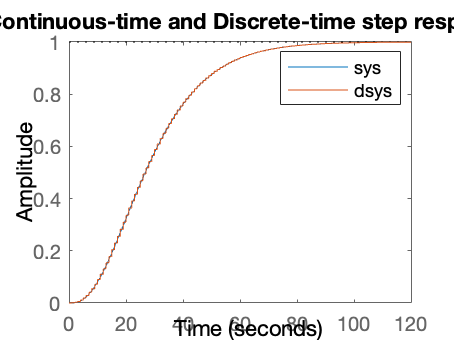

% Y(s) = 1/(1+s*tau)ˆ3*U(s)
% Find discrete time model
% Show dependancy of a(d) and b(d) parameters on
% time constant tau
Ts = 1;
% Assume ARX model structure

time = 1000;
T = 0:Ts:time-1;
T_all = 0:Ts:3*time-1;
% Solution
% Continuous-time system
tau = 10;
sys = tf(1,[tau^3 3*tau^2 3*tau 1]);
figure(1);
step(sys);

hold on
% Discrete-time system
dsys = c2d(sys,Ts,'tustin'); % using bilinear approximation 
[response,t] = step(dsys,T);
step(dsys);
title("Continuous-time and Discrete-time step response");
hold off
legend show

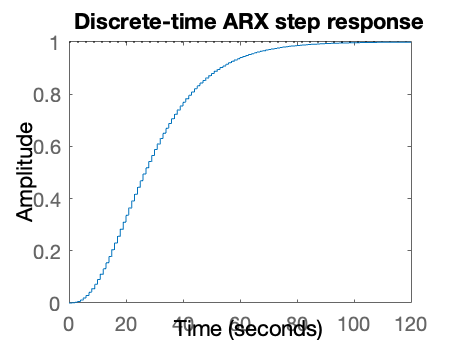

fix_ylim = ylim;
% Discrete-time system ARX

% syms z tau
% b = expand((z+1)*(z+1)*(z+1))
% a = expand((z+1+2*tau*(z-1))*(z+1+2*tau*(z-1))*(z+1+2*tau*(z-1)))

% b = z^3 + 3*z^2 + 3*z + 1
% a = 8*tau^3*z^3 - 24*tau^3*z^2 + 24*tau^3*z - 8*tau^3 + 12*tau^2*z^3 - 12*tau^2*z^2 - 12*tau^2*z + 12*tau^2 + 6*tau*z^3 + 6*tau*z^2 - 6*tau*z - 6*tau + z^3 + 3*z^2 + 3*z + 1

tau1 = 10;
tau = tau1;
b1_ = [1 3 3 1]/(8*tau^3+12*tau^2+6*tau+1);
a1_ = [(8*tau^3+12*tau^2+6*tau+1) (-24*tau^3-12*tau^2+6*tau+3) (24*tau^3-12*tau^2-6*tau+3) (-8*tau^3+12*tau^2-6*tau+1)]/(8*tau^3+12*tau^2+6*tau+1);
c1_ = 1/(8*tau^3+12*tau^2+6*tau+1);

tau2 = 20;
tau = tau2;
b2_ = [1 3 3 1]/(8*tau^3+12*tau^2+6*tau+1);
a2_ = [(8*tau^3+12*tau^2+6*tau+1) (-24*tau^3-12*tau^2+6*tau+3) (24*tau^3-12*tau^2-6*tau+3) (-8*tau^3+12*tau^2-6*tau+1)]/(8*tau^3+12*tau^2+6*tau+1);
c2_ = 1/(8*tau^3+12*tau^2+6*tau+1);

tau3 = 5;
tau = tau3;
b3_ = [1 3 3 1]/(8*tau^3+12*tau^2+6*tau+1);
a3_ = [(8*tau^3+12*tau^2+6*tau+1) (-24*tau^3-12*tau^2+6*tau+3) (24*tau^3-12*tau^2-6*tau+3) (-8*tau^3+12*tau^2-6*tau+1)]/(8*tau^3+12*tau^2+6*tau+1);
c3_ = 1/(8*tau^3+12*tau^2+6*tau+1);

dsysARX = tf(b1_,a1_,Ts,'Variable','z^-1');
figure(2);
step(dsysARX);
title("Discrete-time ARX step response");

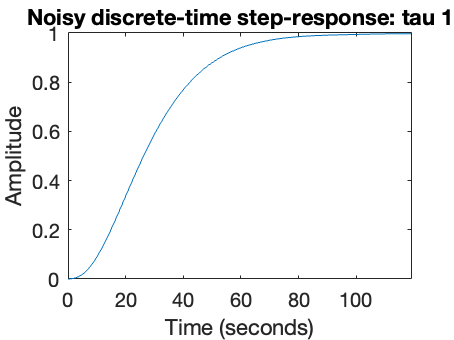


% Noisy discrete-time system
He = tf(c1_, a1_, Ts,'Variable','z^-1');  
step_input = ones(time,1);

variance = 0.01;
response = lsim(dsysARX,step_input,T);
noisevec = lsim(He,sqrt(variance)*randn(time,1),T);
y = response+noisevec;
figure(3);
plot(t(1:120),y(1:120));
title("Noisy discrete-time step-response: tau 1");
ylabel("Amplitude");
xlabel("Time (seconds)");

## Problem 2:

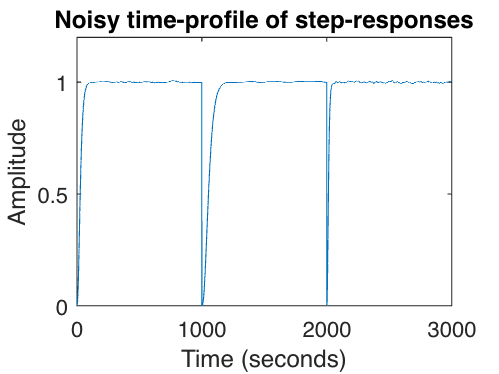


% Consider time profile

% Plan:
% Plot model from 0 to 3000 with constant tau1
% Implement if statements that change tau for each of the periods
% Plot the profile
% Do not forget the noise

% Solution
input = ones(3*time,1);       % step signal
time_profile = computeTimeProfile(input,Ts,tau1,tau2,tau3);
figure(4);
grid on;
plot(T_all',time_profile);  % time-profile
title("Noisy time-profile of step-responses");
ylabel("Amplitude");
xlabel("Time (seconds)");

## Problem 3:

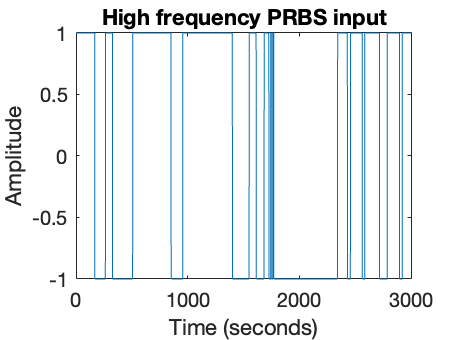

% Generate input-output data
% Use excitation signals
% Pseudo-binary sequence with 
% low frequency, white noise, high frequency
% Select the signal

% input sequence - low frequency input
p_switch = 0.01;
UU_low = createSignal(p_switch,3*time);
figure(5);
plot(T_all',UU_low);
title("Low frequency PRBS input");
ylabel("Amplitude");
xlabel("Time (seconds)");

% input sequence - white noise input
p_switch = 0.5; 
UU_white = createSignal(p_switch,3*time);
%plot(T_all',UU_white);
title("White noise PRBS input");
ylabel("Amplitude");
xlabel("Time (seconds)");

% input sequence - high frequency input 
p_switch = 0.9; 
UU_high = createSignal(p_switch,3*time);
%plot(T_all',UU_high);
title("High frequency PRBS input");
ylabel("Amplitude");
xlabel("Time (seconds)"); 

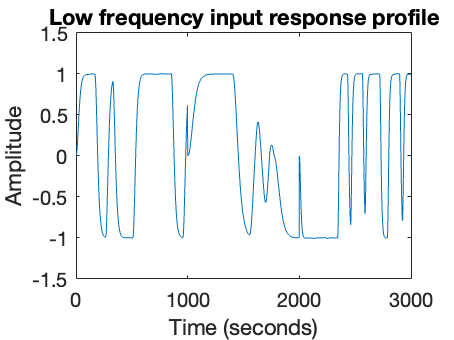


input = UU_low;      % low-frequency signal
time_profile_low = computeTimeProfile(input,Ts,tau1,tau2,tau3);
figure(6);
plot(T_all',time_profile_low); 
title("Low frequency input response profile");
ylabel("Amplitude");
xlabel("Time (seconds)");

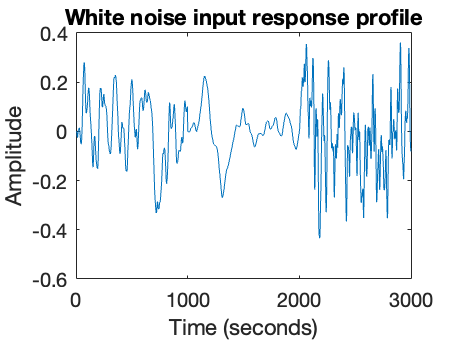


input = UU_white;      % white-noise signal
time_profile_white = computeTimeProfile(input,Ts,tau1,tau2,tau3);
figure(7);
plot(T_all',time_profile_white);
title("White noise input response profile");
ylabel("Amplitude");
xlabel("Time (seconds)");

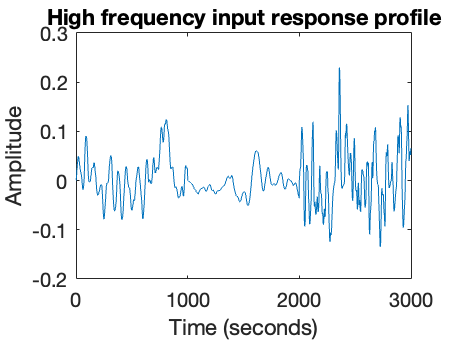


input = UU_high;      % high-frequency signal
time_profile_high = computeTimeProfile(input,Ts,tau1,tau2,tau3);
figure(8);
plot(T_all',time_profile_high); 
title("High frequency input response profile");
ylabel("Amplitude");
xlabel("Time (seconds)");


% Conclusion
% Because white-noise and high-frequency input signal
% do not show clearly dynamical changes
% the low-frequency input signal has been chosen


% Problem 4:
% Perform parameters tracking using different forgetting methods
% For each of the signals obtained before

% Linear
% Exponential
% Time Varying exponential
% Restricted
% Use of prior information

A0 = [1	-3	2 -2];
B0 = [0.0001	0.0003	0.0003	0.0001];
% input = UU_low;
% output = time_profile_low;
% 
% % No forgetting
% lambda = 1.0;
% initCov = variance;
% figure(9);
% ttl = 'ARX model parameters: no FF';
% forgetting(input,output,initCov,lambda,A0,B0,a1_,a2_,a3_,b1_,b2_,b3_,ttl);
% 
% % Forgetting
% lambda = 0.998;
% initCov = variance;
% figure(10);
% ttl = 'ARX model parameters: FF';
% forgetting(input,output,initCov,lambda,A0,B0,a1_,a2_,a3_,b1_,b2_,b3_,ttl);


% A0 = [1	-3	2 -2];
% B0 = [0.0001	0.0003	0.0003	0.0001];
% input = UU_white;
% output = time_profile_white;
% 
% % No forgetting
% lambda = 1.0;
% initCov = variance;
% figure(11);
% ttl = 'ARX model parameters: no FF';
% forgetting(input,output,initCov,lambda,A0,B0,a1_,a2_,a3_,b1_,b2_,b3_,ttl);
% 
% % Forgetting
% lambda = 0.998;
% initCov = variance;
% figure(12);
% ttl = 'ARX model parameters: FF';
% forgetting(input,output,initCov,lambda,A0,B0,a1_,a2_,a3_,b1_,b2_,b3_,ttl);

% A0 = [1	-3	2 -2];
% B0 = [0.0001	0.0003	0.0003	0.0001];
% input = UU_high;
% output = time_profile_high;
% 
% % No forgetting
% lambda = 1.0;
% initCov = variance;
% figure(13);
% ttl = 'ARX model parameters: no FF';
% forgetting(input,output,initCov,lambda,A0,B0,a1_,a2_,a3_,b1_,b2_,b3_,ttl);
% 
% % Forgetting
% lambda = 0.998;
% initCov = variance;
% figure(14);
% ttl = 'ARX model parameters: FF';
% forgetting(input,output,initCov,lambda,A0,B0,a1_,a2_,a3_,b1_,b2_,b3_,ttl);


% Problem 5
% Conclusion
% Lessons learned

% Plan
% Describe how each forgetting method affects results of parameter
% estimation
% Describe how does each excitation signal has influence on results of
% parameter estimation

## Implement Forgetting

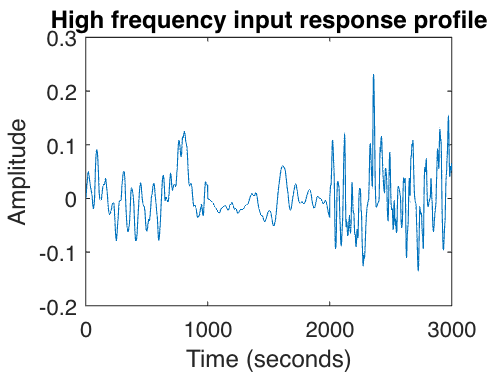

n_samplesBatch = 30;
input = step_input;
response = lsim(dsysARX,step_input,T);
noisevec = lsim(He,sqrt(variance)*randn(time,1),T);
output = response+noisevec;


a_old = A0;
a_new = [1.0000   -1    0.5   -0.2466];
a = a_old;
b = B0;
na = numel(a) - 1;
nb = numel(b);
sig = 0.1;
f = @(z, a, b) a(2:end)*z(1:na) + b*z(na + 1:end) + sig*randn();
n_samples = 1000;

y_est = zeros(n_samples, 1);
y_est(4:n_samplesBatch) = output(4:n_samplesBatch);
y = output;
u = input;
theta = zeros(na + nb, n_samples);
P=eye();
for i = na+1:n_samples
%     if i > n_samples
%         a = a_new;
%     end
    % Regresor construction
    z = [-y(i - 1:-1:i-na); u(i:-1:i-nb + 1)];
    y_est(i) = f(z, a, b);
    
    % Zeta
    zeta = z'*P*z;
    
    % Prediction error
    epsilon = y(i) - z'*theta(:, i-1);
    
    % Kalman gain
    K = P*z/(1+zeta);
    
    %%  Filtering (Data) step:
    %   Mean value update
    theta(:,i) = theta(:,i-1) + K*epsilon;
    
    %   Covariance update
    P = P - P*z*z'*P/(1+zeta);
    
    P_data_step = P;
    
    %%  Propagation (Time) step:
    %   mean value parameter estimation does not change
    %       theta(t+1|t) = theta(t|t)
    %
    %   updating the covariance matrix
    
    %%%  No forgetting
    %     P = P;
    
    %%%  Linear forgetting
%         V = 0.000001*eye(na + nb);
%         P = P + V;
%     
    %%%  Exponential forgetting
        tef = 1500;
        phi=1-1/tef;
        P=1/phi*P;
    
    %%%  Restricted linear forgetting
%         K = P*z;
%         V = 0.0001*eye(numVariables);
%         zeta_v = z'*V*z;
%         Vo = K*(zeta_v/zeta^2)*K';
%         P = P + Vo;
    
    %%%  Restricted exponential forgetting
%         K = P*z;
%         tef = 250;
%         fi=1-1/tef;
%         zeta_v = (1-fi)/fi * zeta;
%         Vo = K*(zeta_v/zeta^2)*K';
%         P = P + Vo;
    
    P_time_step = P;
end
G_truth = dsysARX;
G_truth.Name = 'G truth';

G_new = tf(theta(na+1:end, end)',[1 theta(1:na, end)'],1,'Variable','z^-1');
G_new.Name = 'G estimated';
hold off

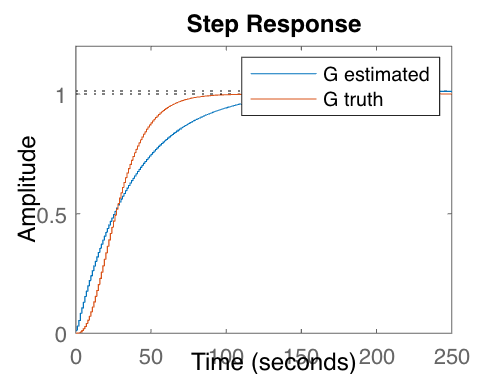

figure(15);
step(G_new);
hold on
step(G_truth);
hold off
legend show

fix_ylim = ylim;

## Additional tools

% Storing figures
if storeFigures
    for i=1:14
        filename = strcat('figure_',num2str(i));
        foldername = './figures/';
        saveas(figure(i),fullfile(foldername,filename),'jpg');
    end
end

% input = UU_low;
% output = time_profile_low;
% na = 3;
% nb = 4;
% nk = 0;
% nc = 1;
% z = [output,input];
% opt = arxOptions('InitialCondition','zero','Display','off');
% sysARX = armax(z,[na nb nc nk],opt);
% He = tf(c1_, a1_, Ts,'Variable','z^-1');
% response = lsim(sysARX,input,T_all');
% noisevec = lsim(He,sqrt(variance)*randn(length(input),1),T_all');
% y = response+noisevec;
% figure(16);
% plot(T_all',y);
% hold on
% plot(T_all',time_profile_low);
% title("Noisy discrete-time step-response");
% ylabel("Amplitude");
% xlabel("Time (seconds)");
% hold off